# Beam pattern analysis (Vicon + Avisoft)

Beam direction (azimuth/elevation) with microphone auto-selection depending on animal position and occluder. 

## Paths — set once

Beampatten_path = 'Z:\Rie\Analysis\Beampattern_analysis';
addpath(Beampatten_path);                                 % estimate_beam_direction, run_beamaim_maze, bp_proc_vicon, ...
addpath(fullfile(Beampatten_path,'bp_preprocessing'));    % get_call_fcn, compensate_call_dB_fcn, air_absorption_vec, ... (self-contained)

## 1. Specify the trial

bat        = 'batA125';
date_str   = '20260710';        % YYYYMMDD
trial_num  = 8;                 % numeric trial number
bat_pos_trial = '08';           % index used in the bat_pos filename (may differ from trial_num)
detect_status = 'done';         % 'done' or 'in progress' 

% roots (match call_detect's two path constants)
RAW_ROOT    = 'Z:\Rie\Data\Raw_Data';
Call_ROOT = 'Z:\Rie\Data\Preprocessing\Mic\Mic_Data_Detected';
POS_ROOT    = 'Z:\Rie\Analysis\position_processing';

% build the file paths
combined_file = fullfile(RAW_ROOT, bat, date_str, 'Mic_data', 'Combined_trial_data', ...
                         sprintf('T%07d_combined.mat', trial_num));
detected_file = fullfile(Call_ROOT, bat, detect_status, ...
                         sprintf('%s_T%07d_detected.mat', date_str, trial_num));
bat_pos_file  = fullfile(POS_ROOT, 'Bat_Position', ...
                         sprintf('%s_%s_%s_bat_pos.mat', bat, date_str, bat_pos_trial));
mic_pos_file  = fullfile(POS_ROOT, 'Mic_positions', sprintf('mic_pos_%s.mat', date_str));

% sanity-check they exist
assert(isfile(detected_file), 'detected_file not found: %s', detected_file);
assert(isfile(bat_pos_file),  'bat_pos_file not found: %s',  bat_pos_file);
assert(isfile(mic_pos_file),  'mic_pos_file not found: %s',  mic_pos_file);

## 2. Produce the bp_proc_file (stage 0: preprocessing)

Temperature/humidity are left EMPTY -> pulled from the detected file's meta (call_detect auto-fills them from the master metadata CSV).

cfg = struct();
cfg.combined_file     = combined_file;
cfg.detected_file     = detected_file;
cfg.bat_pos_file      = bat_pos_file;
cfg.mic_pos_file      = mic_pos_file;
% params template + DSP helpers are auto-located in .\bp_preprocessing (self-contained)
cfg.tempC = [];               % [] -> auto from detected meta
cfg.humid = [];               % [] -> auto from detected meta
cfg.pos_units   = 'mm';       % Vicon positions in mm -> converted to metres
cfg.axis_orient = [1 2 3];    % column order to get [x y z]
cfg.head_normal = [0 0 1];    % assumed head-up normal for the marker-free track
cfg.mic_sens_file = '';       % '' -> uniform Knowles FG (flat sensitivity)
cfg.mic_bp_file   = '';       % '' -> uniform Knowles FG (omnidirectional)
cfg.mic_sens_dB   = 0;
cfg.out_dir = '';
cfg.bat_id = bat;
cfg.out_name = '';            % '' -> derived (e.g. 20260625_T0000008)
cfg.extract_call_len_ms = 15;   % widen from default 10 ms

data = bp_proc_vicon(cfg);    % writes <out_name>_mic_data_bp_proc.mat into out_dir

Using T = 22.5 C, H = 43 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: using 24 of 31 mics (mic rows [1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24]).
Call duration marking is problematic in Call #117  [marked start is 792 pt(s) BEFORE the extraction window]
Call duration marking is problematic in Call #193  [marked end is 1043 pt(s) AFTER the extraction window (win=3750 pt)]
Call duration marking is problematic in Call #200  [marked end is 962 pt(s) AFTER the extraction window (win=3750 pt)]
Added take-off-centred coords (data.takeoff_centered): pivot [-993.1 1568.1] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260710_T0000008_mic_data_bp_proc.mat (79 calls with track)


## 4. Estimate beam-aim with auto mic selection

bp_proc_file = data.saved_file;

bcfg = struct();
bcfg.bp_proc_file  = bp_proc_file;
bcfg.bat_pos_file  = bat_pos_file;
bcfg.freq_desired  = 35;      % kHz
bcfg.sync_offset_s = 0;       % Vicon<->Avisoft offset (s) -- set once alignment is known
bcfg.save_back     = true;    % write beam-aim fields back into bp_proc_file
% bcfg.est_opts = struct('method','anchored','anchor_win_deg',40,'min_mics_fit',5);  % optional

out = run_beamaim_maze(struct( ...
        'bp_proc_file', bp_proc_file, ...
        'bat_pos_file', bat_pos_file, ...
        'mic_select',   'lineofsight'));     % use 'zone' for the old static per-zone lists

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 4.600274. Normalizing...

Data is not normalized! The pdf sums to: 4.706167. Normalizing...

Data is not normalized! The pdf sums to: 5.663633. Normalizing...

Data is not normalized! The pdf sums to: 6.876106. Normalizing...

Data is not normalized! The pdf sums to: 9.421082. Normalizing...

Data is not normalized! The pdf sums to: 4.087807. Normalizing...

Data is not normalized! The pdf sums to: 2.113082. Normalizing...

Data is not normalized! The pdf sums to: 2.135529. Normalizing...

Data is not normalized! The pdf sums to: 3.570230. Normalizing...

Data is not normalized! The pdf sums to: 5.866829. Normalizing...

Data is not normalized! The pdf sums to: 4.293031. Normalizing...

Data is not normalized! The pdf sums to: 3.061753. Normalizing...

Data is not normalized! The pdf sums to: 2.248349. Normalizing...

Data is not normalized! The pdf sums to: 2.445245. Normalizing...

Data is not no

## 5. QC the estimated beam directions

plot_beamaim_qc(bp_proc_file, out);

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260710_T0000008_beamaim_qc.png


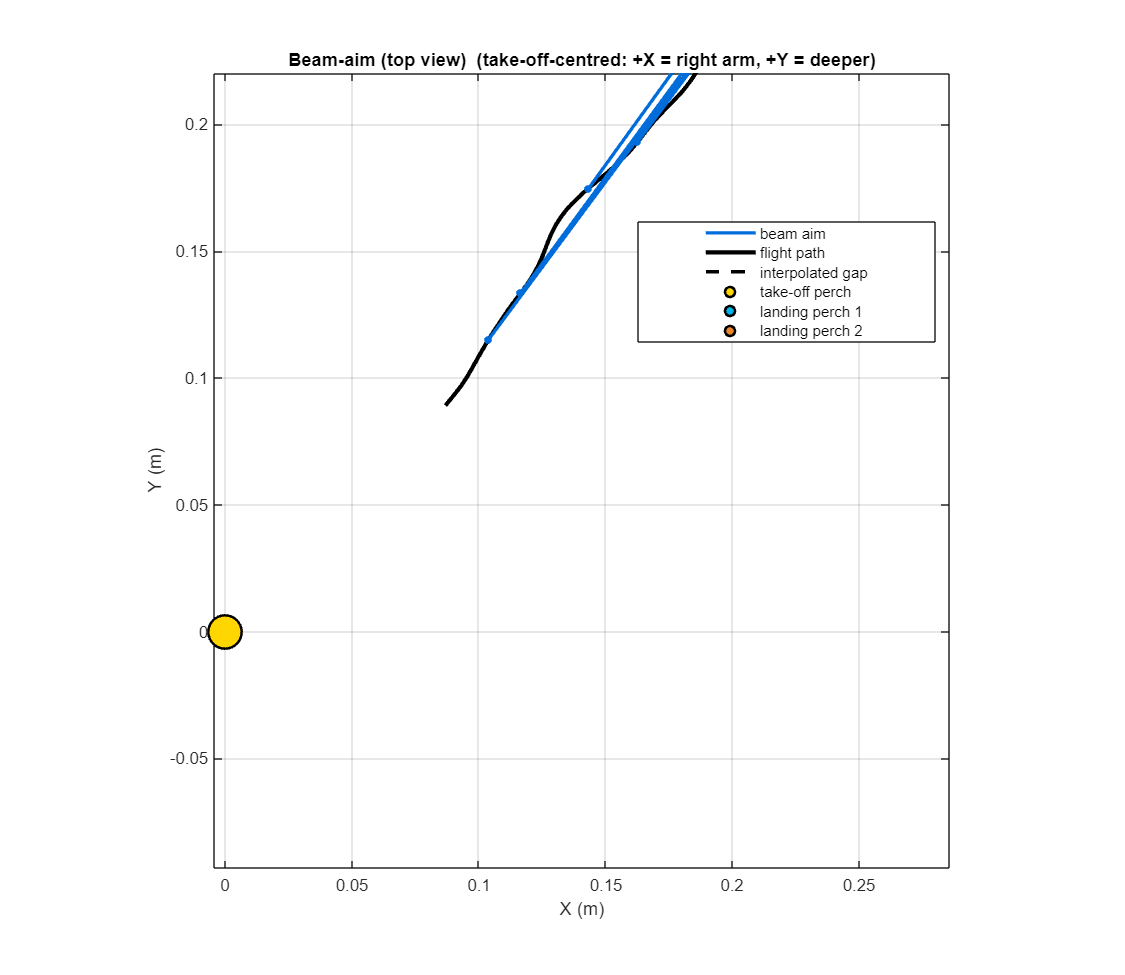


xlim([-4.48 2.78])
ylim([-4.44 2.18])
legend("Position", [0.56675,0.64829,0.265,0.12596])

 
landingPerch = findobj(gcf, "DisplayName", "landing perch")

landingPerch =   0×0 empty GraphicsPlaceholder array.


datatip(landingPerch,-2.492,-0.7226);

Error using datatip
First argument must be a chart object that supports data tips.

## **6. Trial level analysis**

% res = run_trial_analysis(struct( ...
%         'bp_proc_file', bp_proc_file, ...
%         'bat_pos_file', bat_pos_file, ...
%         'plot', true));
% disp(res.trial_row)
% fprintf('pre-flight calls: %d\n', height(res.preflight_calls));